# trac boom - cylinder conversion

% Trac boom parameters
clear all
close all

% length
L=29.5; % m

% Linear density
rho_l = 0.1; % kg/m

% Cross sectional area
% 6.4e-5 to 7e-5 m^2 
A_trac = 6.75e-5; %m^2

% Second moment of area
moi_trac = 6.2e-8; %m^4 

% Yound modulus(modulus of elasticity)
% 80-500 GPa 
E_trac = 80; %GPa

% compute EI/A for trac boom
eia_trac = E_trac*moi_trac/A_trac

eia_trac = 0.0735

% = E (r^4*pi/4) (1/(pi*r^2) ) = E r^2 1/4

% Modulus (E) and cylinderical boom radius (r) rquired to have the same
% values for EI/A as the trac boom

Ex = linspace(20,100,100);
hold on
plot(Ex, (4*eia_trac./(Ex)).^(1/2) )
plot(E_trac,(4*eia_trac./(E_trac)).^(1/2) , 'ro')
title("Cylinder Boom Radius vs. Youngs Modulus to Match Trac Boom")
xlabel("Youngs Modulus - GPa")
ylabel("Boom Radius - m")
legend("Variable Modulus","E_{trac} = E_{cyl}")
hold off


% parameters for analogous boom
E_boom = E_trac % GPa

E_boom = 80

r_boom = sqrt(4*eia_trac/E_boom) % meters

r_boom = 0.0606

A_boom = pi*r_boom^2 % m^2

A_boom = 0.0115

moi_boom = pi/4*r_boom^4

moi_boom = 1.0602e-05


% approximate natural frequencies w_n = (1/mass * EI/area)^(1/2)
w_n_trac = 180/pi * sqrt(1/(rho_l*L) *E_trac*moi_trac/A_trac )

w_n_trac = 9.0428

w_n_boom = 180/pi * sqrt(1/(rho_l*L) *E_boom*moi_boom/A_boom )

w_n_boom = 9.0428

## Match just EI, now A

clear all

clc

% length
L=29.5; % m

% Linear density
rho_l = 0.1; % kg/m

% Cross sectional area
% 6.4e-5 to 7e-5 m^2 
A_trac = 6.75e-5; %m^2

% Second moment of area
moi_trac = 6.2e-8; %m^4 

% Yound modulus(modulus of elasticity)
% 80-500 GPa 
E_trac = 80; %GPa

% compute EI/A for trac boom
ei_trac = E_trac*moi_trac

ei_trac = 4.9600e-06

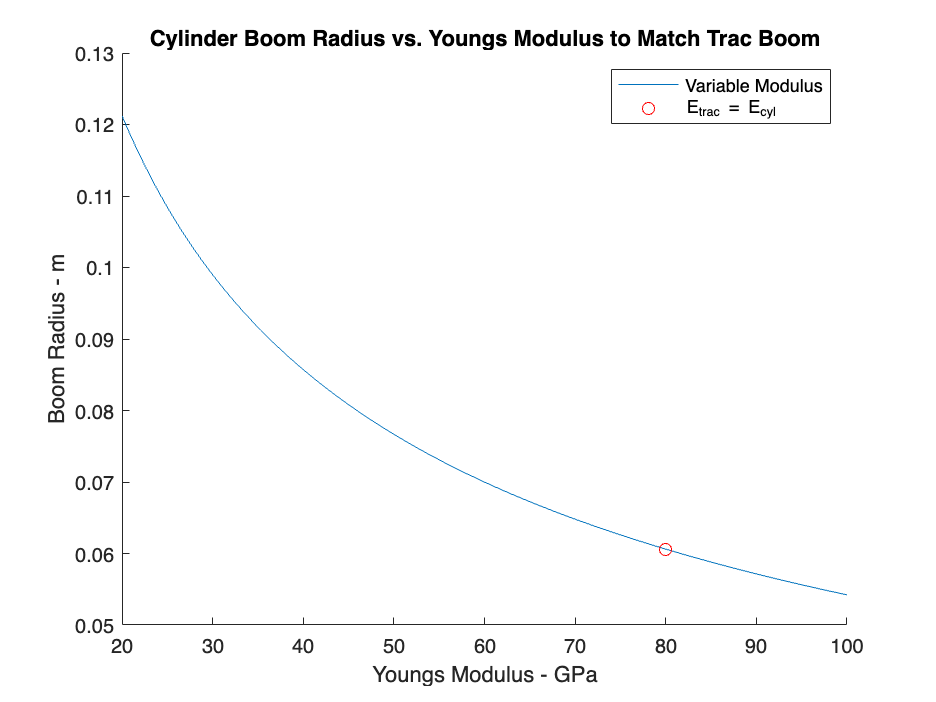

% = E (r^4*pi/4) ) = 

% Modulus (E) and cylinderical boom radius (r) rquired to have the same
% values for EI/A as the trac boom

Ex = linspace(20,100,100);
plot(Ex, (4*ei_trac./(Ex)).^(1/4) )
hold on
plot(E_trac,(4*ei_trac./(E_trac)).^(1/4) , 'ro')
title("Cylinder Boom Radius vs. Youngs Modulus to Match Trac Boom")
xlabel("Youngs Modulus - GPa")
ylabel("Boom Radius - m")
legend("Variable Modulus","E_{trac} = E_{cyl}")
hold off

% parameters for analogous boom
E_boom = E_trac % GPa

E_boom = 80

r_boom = sqrt(4*ei_trac/E_boom) % meters

r_boom = 4.9800e-04

A_boom = pi*r_boom^2 % m^2

A_boom = 7.7911e-07

moi_boom = pi/4*r_boom^4

moi_boom = 4.8305e-14


% approximate natural frequencies w_n = (1/mass * EI/area)^(1/2)
w_n_trac = 180/pi * sqrt(1/(rho_l*L) *E_trac*moi_trac/A_trac )

w_n_trac = 9.0428

w_n_boom = 180/pi * sqrt(1/(rho_l*L) *E_boom*moi_boom/A_boom )

w_n_boom = 0.0743